%%Hydrological model. 
% Implement the hydrological model on the 6-year-long series of precipitation and discharge.
clear 
close


%% Load data
load area_rating_curve.txt
load kc.txt
load P.txt
load Q_obs.txt
load temperature.txt

Nyears_Q=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
hour_month=day_month*24;
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month
month_end_hour=cumsum(hour_month);                  
month_start_hour=month_end_hour-hour_month+1;
Q_hour_year=reshape(Q_obs,365*24,Nyears_Q);
P_hour_year=reshape(P,365*24,Nyears_Q);

%%Parameters for the hydrological model
sw = 0.25;      %[-] Wilting point
s1 = 0.4;       %[-] Soil moisture stress threshold
n = 0.3;        %[-] Porosity
Q_b = 7;        %[m^3/s] Baseflow
t_sup = 22;     %[h] Mean superficial residence time
A = 4000;       %[km^2] Catchment area
phi = 38;       %[°] Latitude 

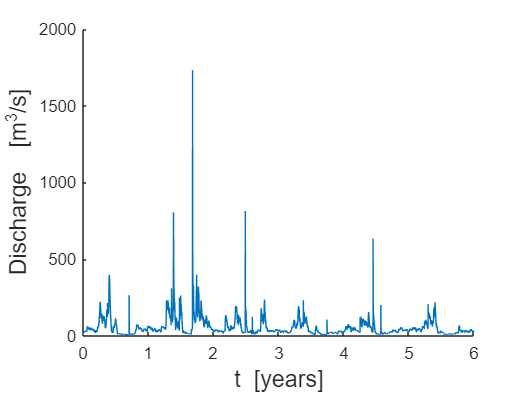

%% Plot discharge time series

figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

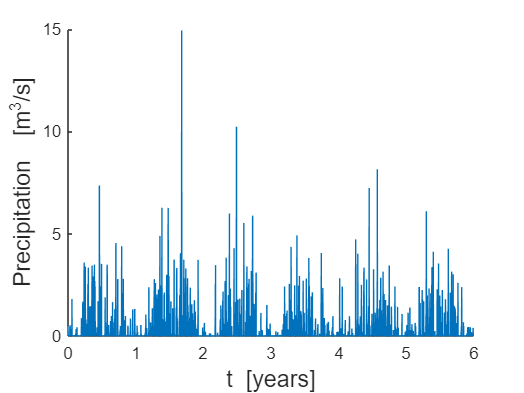


%% Plot precipitation time series

figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [m^{3}/s]','FONTSIZE',14)   %insert label y axis
box off

%% 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) 
% through the Thornthwaite equation 

I= sum((temperature./5).^(1.514)) ; %heat index
a= 6.75*(10^(-7))*(I^3) - 7.71*(10^(-5))*(I^2) + 1.79*(10^(-2))*I + 0.49; %experimental exponent
D = 1:365;
delta = 0.409*sin((2*pi*D/365)-1.39);
w_s = acos(-tan(phi)*tan(delta));
N_D = 24*w_s/pi; %number of daylight hours of day D
N_M =zeros(12,1); % mean daylight hours of month m

for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = (16/12)*N_M.*((10*temperature/I).^a); % [mm/unit area]

%% 2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.
% Hydrological model: to be calibrated

K_sat = 10e-6;      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5
c = 1;              %[-] Exponent for power-law relation L(s)  1<c<20
z = 1;              %[L] Root zone depth 1<z<2000 [mm]
t_sub = 1;          %[T] Mean sub-superficial residence time 1<t_sub<400

%% 3. Use an Euler explicit scheme to integrate the system of equations at hourly scale
% (see Table 2).

s = zeros(length(Q_obs),1);
s(1) = 0.5; % initial arbitrary value
Vsup = zeros(length(Q_obs),1);
Vsup(1) = 0.5; 
Vsub = zeros(length(Q_obs),1);
Vsub(1) = 0.5; 
K_sat_vect = ones(length(P),1)*K_sat;
I = min(P,K_sat_vect);
I_hour_year = reshape(I,365*24,Nyears_Q);
R = P-I;
R_hour_year = reshape(R,365*24,Nyears_Q);
ET_hour_year = zeros(size(Q_hour_year));
L = zeros(length(Q_obs),1);


for y=1:Nyears_Q
    for m=1:12
        for h=month_start_hour(m):month_end_hour(m)
            t=(y-1)*8760+h;
            if s(t)<=sw && s(t)>=0
                ET_hour_year(h,y)= 0;
            elseif s(t)<=s1 && s(t)>sw
                ET_hour_year(h,y)= kc(m)*ET_0(m)*((s(t)-sw)/(s1-sw))
            elseif s(t)<=1 && s(t)>s1
                ET_hour_year(h,y)= kc(m)*ET_0(m);
            end
            L(t)=K_sat*(s(t)^c);
            s(t+1)=s(t)+((I(t)-ET_hour_year(h,y)-L(t))*(1/(n*z)));
            Vsup(t+1)=Vsup(t)+R(t)-((t_sup^(-1))*Vsup(t));
            Vsub(t+1)=Vsub(t)+L(t)-((t_sub^(-1))*Vsub(t));
        end
    end
end


ET=reshape(ET_hour_year,[],1);
qsup=(t_sup^(-1)).*Vsup;
qsub=(t_sub^(-1)).*Vsub;
Qsup=A*qsup;
Qsub=A*qsub;

%% 4. Test the mass balance of your system in order to ensure a correct implementation.

doTest=1;
dt=1;

%compute total discharge Q
if doTest % if doTest=1, check mass balance
    P_tot=sum(P)*dt;
    R_tot=sum(R)*dt;
    L_tot=sum(L)*dt;
    ET_tot=sum(ET)*dt;
    %"testS" balance for the root zone (input/output). testS = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testS=P_tot/(ET_tot+R_tot+L_tot+n*z*(s(end)-s(1)))

    %"testQ" balance for the whole system (input/output). testQ = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testQ=sum(P-ET)/(sum(qsup+qsub)+n*z*(s(end)-s(1))+Vsup(end)+Vsub(end))
end

testS = 1.0000

testQ = 0.9998